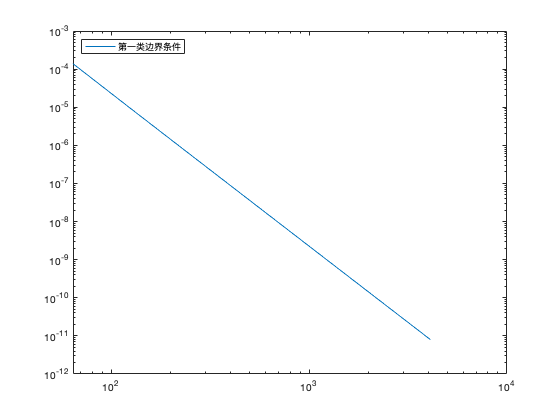

clear, clc, clf
LW = 'linewidth'; lw = 2;

maxError1 = zeros(7, 1);
maxError2 = zeros(7, 1);
maxError3 = zeros(7, 1);
kk = linspace(6, 12, 7);
nn = 2.^kk;
for k = 6:12
    n = 2^k;
    x = linspace(-1, 1, n + 1)';
    % xtest =
    F = @(x)exp(3 .* cos(pi .* x));
    f = F(x);
    %%
    h = diff(x);
    df = diff(f);
    lambda = h(2:n) ./ (h(2:n) + h(1:n - 1));
    d = 6 * (df(2:n) ./ h(2:n) - df(1:n - 1) ./ h(1:n - 1)) ./ (h(2:n) + h(1:n - 1));
    mu = 1 - lambda;
    %%
    %第一类边界条件
    M0 = 3*pi^2*exp(-3);
    Mn = 3*pi^2*exp(-3);
    A1 = diag(2 * ones(n - 1, 1)) + diag(lambda(1:n - 2), 1) + diag(mu(2:n - 1), -1);
    D1 = [d(1) - mu(1) * M0; d(2:n - 2); d(n - 1) - lambda(n - 1) * Mn];
    M1 = A1 \ D1;
    M1 = [M0; M1; Mn];
    %%
    %第二类边界条件
    m0 = 0;
    mn = 0;
    lambda2 = [1; lambda];
    mu2 = [mu; 1];
    d0 = 6 * (df(1) / h(1) - m0) / h(1);
    dn = 6 * (mn - df(n) / h(n)) / h(n);
    D2 = [d0; d; dn];
    A2 = diag(2 * ones(n + 1, 1)) + diag(lambda2, 1) + diag(mu2, -1);
    M2 = A2 \ D2;
    %%
    %第三类边界条件
    lambda0 = h(1) / (h(1) + h(n));
    lambda3 = [lambda0; lambda(1:n - 2)];
    mu0 = 1 - lambda0;
    d0 = 6 * (df(1) ./ h(1) - df(n) ./ h(n)) / (h(1) + h(n));
    D3 = [d0; d];
    A3 = diag(2 * ones(n, 1)) + diag(lambda3, 1) + diag(mu, -1);
    A3(1, n) = mu0;
    A3(n, 1) = lambda(n - 1);
    M3 = A3 \ D3;
    M3 = [M3; M3(1)];
    %%
%     figure(1)
    maxError1(k - 5) = CubicSpline(x, F, h, M1);
    % subplot(3, 1, 1)
    % title('第一类边界条件')
%     figure(2)
    maxError2(k - 5) = CubicSpline(x, F, h, M2);
    % subplot(3, 1, 2)
    % title('第二类边界条件')
%     figure(3)
    maxError3(k - 5) = CubicSpline(x, F, h, M3);
    % subplot(3, 1, 3)
    % title('第三类边界条件')
end
figure(1);
loglog(nn, maxError1)%, hold on
% loglog(nn, maxError2), hold on
% loglog(nn, maxError3)
legend('第一类边界条件', '第二类边界条件', '第三类边界条件', 'location', 'nw')

function maxTestError = CubicSpline(x, F, h, M)
    % LW = 'linewidth'; lw = 2;
	% n = 2^6;
	n = size(x) - 1;
    f = F(x);
    maxTestError = 0;

    for k = 1:n
        %     m = 100;
        %     xx = linspace(x(k), x(k+1), m)';
        testPoint = linspace(x(k), x(k + 1), 6)';
        S = ((x(k + 1) - testPoint).^3 * M(k) + (testPoint - x(k)).^3 * M(k + 1)) / (6 * h(k)) + ...
            ((x(k + 1) - testPoint) * f(k) + (testPoint - x(k)) * f(k + 1)) / h(k) - ...
            h(k) * ((x(k + 1) - testPoint) * M(k) + (testPoint - x(k)) * M(k + 1)) / 6;
        %     subplot(2,1,1)
        %     p1 = plot(xx, F(xx), 'k', LW, lw); hold on
        %     p2 = plot(xx, S, 'r', LW, lw); hold on
        %     subplot(2,1,2)
        %     error = abs(F(xx) - S);
        testError = abs(F(testPoint) - S);
        maxThisRound = max(testError);
        maxTestError = max(maxTestError, maxThisRound);
        %     p3 = semilogy(xx(2:end-1), error(2:end-1), 'b', LW, lw); hold on
    end

    % p1 = plot(n, maxTestError, 'b'); hold on
    % legend(p1, 'max error', 'location', 'nw')
    % subplot(2,1,1)
    % legend([p1,p2], 'exact', 'interpolant')
    % subplot(2,1,2)
    % legend(p3, 'error', 'location', 'se')
end
